## Cold plate parameterization 

In this subsection, the geometry of the cold plate can be designed, use this to vary different geometric parameters and caluculate the resulting performance parameters such as surface area relevant for heat transfer and heat transfer cofficient.

The following schematic shows the relevant input parameters that can be selected:

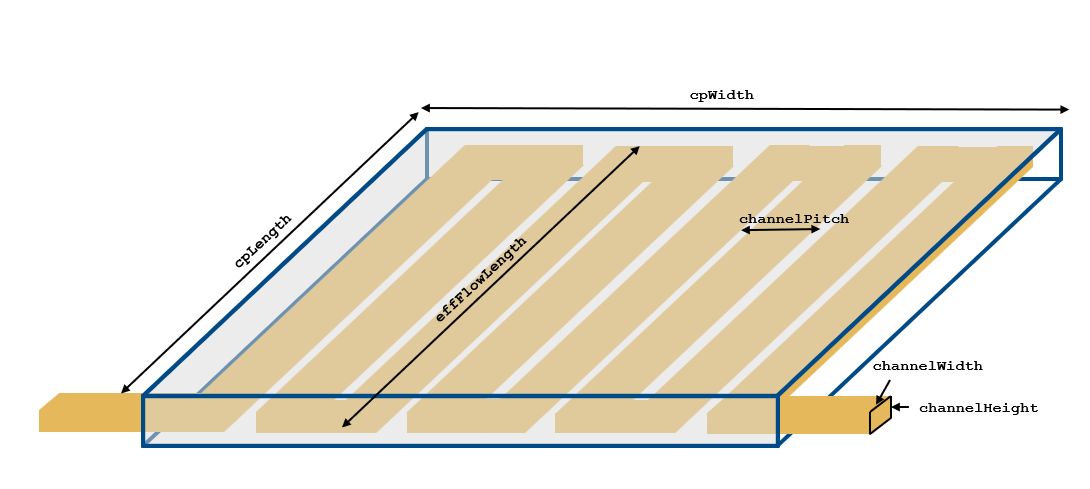

#### Geometric and material parameters of cold plate and cold plate channels:

cpLength            = simscape.Value(250, 'mm');     % (mm)
cpWidth             = simscape.Value(160, 'mm');     % (mm)
cpThickness         = simscape.Value(6, 'mm');       % (mm)

channelWidth        = simscape.Value(5, 'mm');       % (mm)
channelHeight       = simscape.Value(10, 'mm');       % (mm)
channelMargin       = simscape.Value(5, 'mm');       % mm
channelPitch        = simscape.Value(10, 'mm');       % mm

% Check feasability of values
checkColdPlateGeometry(cpLength.value('mm'), cpWidth.value('mm'), cpThickness.value('mm'),...
    channelWidth.value('mm'),channelHeight.value('mm'),channelMargin.value('mm'),channelPitch.value('mm'));


#### Additional parameters and cold plate material parameters

deviceD              = simscape.Value(75, 'mm');      % mm
cpK                  = simscape.Value(167, 'W/(m*K)');% (W/(m*K))
channelRoughness     = simscape.Value(15e-6, 'm');    % (m)


#### Calculate derivative parameters

effFlowLength         = cpLength - 2*channelMargin;                                 % Effective flow length of channels
numPasses             = floor((cpWidth - 2*channelMargin)/channelPitch);            % Number of channel passes based on the channel pitch
cpDeviceSurfaceArea   = pi*(deviceD/2)^2;                                           % Thickness of device
channelLength         = numPasses*effFlowLength;                                    % Derived total channel length  
channelArea           = channelHeight*channelWidth;                                 % Channel cross-sectional area 
channelDh             = 2*channelWidth*channelHeight/(channelHeight+channelWidth);  % Channel hydraulic diameter 
channelHTCSurfaceArea = channelLength*2*(channelWidth+channelHeight);               % Channel surface area for convective heat transfer


#### Calculate performance

The convective heat transfer coefficient in the cold channels can be determined using the Gnielinksi correlation. This is the same approach that is being used inside the Pipe (TL) component. For simplicity, we are using the fluid properties at an assumed inlet temperature of 25°C. The Reynolds number laminar flow upper limit and the Reynolds number turbultent flow lower limit is assumed to be at 2000 and 4000 respectively. This is then used to determine the thermal resistance of the convective heat transfer path. 

htc = calculateHTCPipe(channelDh,channelArea, mDot, 2000, 4000, kCoolant,channelRoughness/channelDh,muCoolant,PrCoolant);
Rconv  = 1/(htc*channelHTCSurfaceArea);


The thermal resistance due to conduction is then determined using the cold plate specifications and its material properties

Rcond  = cpThickness*1e-3/(cpK*cpDeviceSurfaceArea);

The two combines give the total resistance

Rtotal = Rconv+Rcond;
disp(Rtotal.value('deltaK/W'))

   6.1804e-04

